% load data
clear
clear all
close all
clc
format shorteng
combined_set = readtable("pressure_combined.csv");
x = combined_set{:,1:6}';
y = combined_set{:,7}';

idxTrain = 1:3550;
idxTest = 3551:4176;

x_train = x(:, idxTrain);
y_train = y(:, idxTrain);
x_test = x(:, idxTest);
y_test = y(:, idxTest);
clear combined_set

% load best model
load('pressure_shallow.mat')

% set colours
blue = [0.00 0.00 0.55];
red = [0.65 0.16 0.16];
green = [0.00 0.39 0.00];
pink = [1.00,0.00,1.00];
orange = [0.91,0.41,0.17];

## Training History

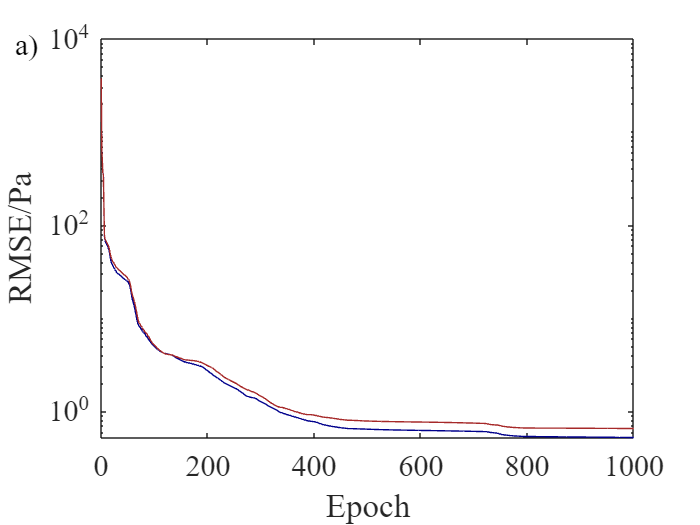

epochs = pressure_shallow_tr.epoch;
training_RMSE = sqrt(pressure_shallow_tr.perf);
testing_RMSE = sqrt(pressure_shallow_tr.tperf);

figure(1)
hold on
plot(epochs,training_RMSE, 'Color', blue)
plot(epochs,testing_RMSE, 'Color', red);
hold off

v=get(1,'currentaxes');
xlabel("Epoch")
ylabel("RMSE/Pa")
% legend("Train", "Test")
set(v,'FontSize',18,'FontName','Times New Roman', 'YScale','log')
box on

annotation('textbox',...
    [0.0099 0.893 0.0472 0.0667],...
    'String',{'a)'},...
    'FontSize',18,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

## Results (Test)

y_test_pred = pressure_shallow_net(x_test);
test_RMSE = rmse(y_test,y_test_pred)

test_RMSE =    656.3055e-003


## Results (All)

y_comb_pred = pressure_shallow_net(x);
comb_RMSE = rmse(y, y_comb_pred)

comb_RMSE =    546.7313e-003


## True vs Predicted Plot

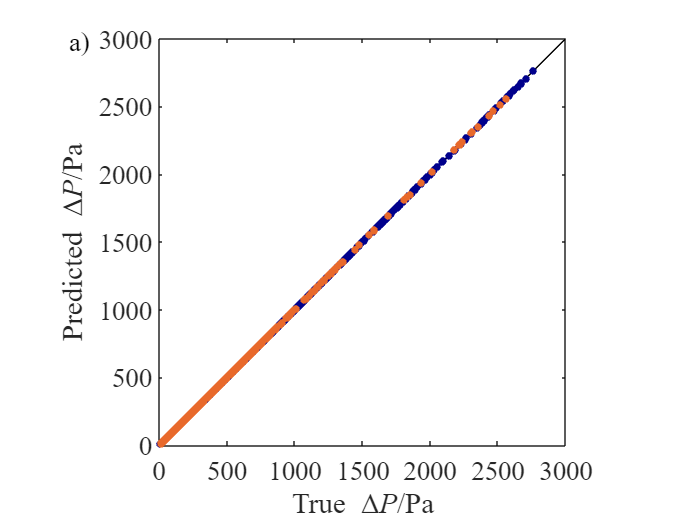

% obtain predictions for train set
y_train_pred = pressure_shallow_net(x_train);
% set axis
axs = [0 3000 0 3000];
line = [0 axs(2)];

figure(2)
hold on
% plot ideal line
plot(line, line, "Color", "k");
% plot points
plot(y_train,y_train_pred,'o','MarkerEdgeColor',blue,'MarkerFaceColor',blue,'MarkerSize',4);
plot(y_test,y_test_pred,'o','MarkerEdgeColor',orange,'MarkerFaceColor',orange,'MarkerSize',4);
hold off

v=get(2,'currentaxes');
xlabel('True\rm \Delta{\itP}/Pa')
ylabel('Predicted \Delta{\itP}/Pa')
% legend('Ideal', '', 'Location', 'nw');
set(v,'FontSize',16,'FontName','Times New Roman', 'XTick', get(v, 'YTick'), 'XTickLabelRotation', 0);
axis(axs)
box on
axis square

% Create textbox
annotation('textbox',...
    [0.087 0.888 0.049 0.0738],'String','a)',...
    'FontSize',16,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

## Others

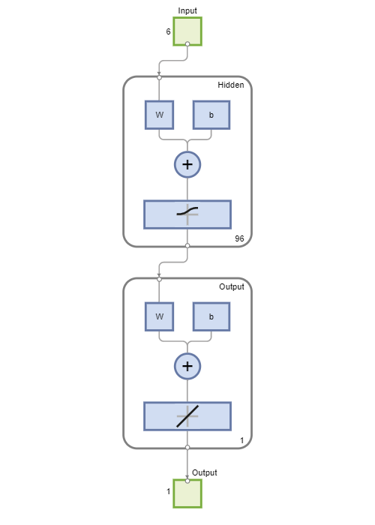

view(pressure_shallow_net);

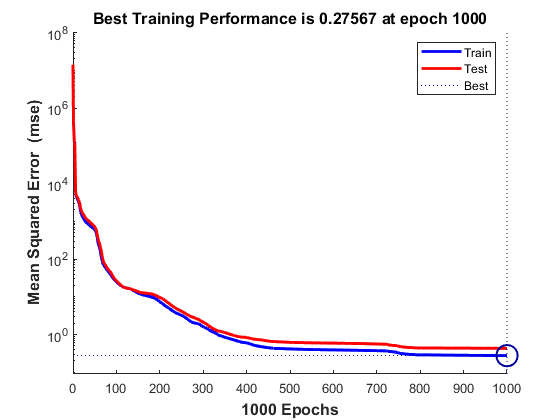

figure, plotperform(pressure_shallow_tr);

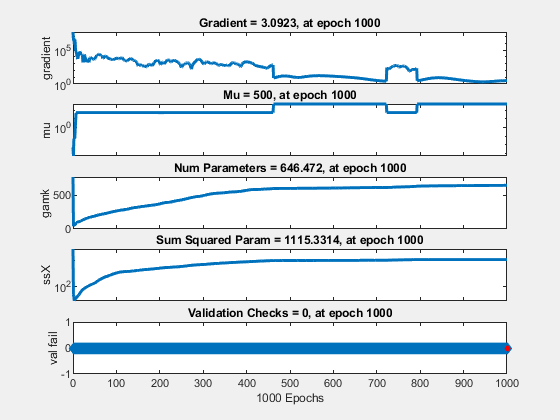

figure, plottrainstate(pressure_shallow_tr);

% e = gsubtract(y_test,y_test_pred);
% figure, ploterrhist(e)
% figure, plotregression(y_test,y_test_pred)

% e = gsubtract(y, y_comb_pred);
% figure, ploterrhist(e)
% figure, plotregression(y,y_comb_pred)